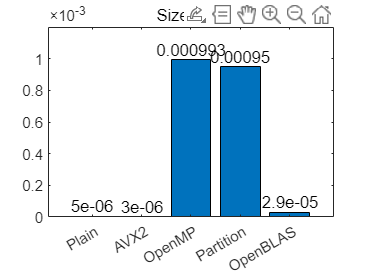

clear
clc
pc = [0.000005;0.000003;0.000993;0.00095;0.000029];
x = ["Plain","AVX2","OpenMP","Partition","OpenBLAS"];
b = bar(x,pc);
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
ylim([0 1.2e-3]),ylabel("time(s)")
title("Size = 16")

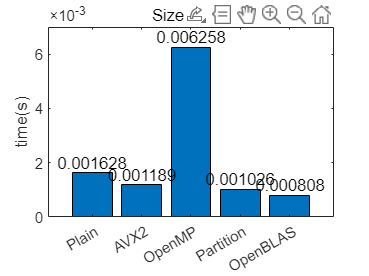

pc = [0.001628 0.001189	0.006258 0.001026 0.000808];
x = ["Plain","AVX2","OpenMP","Partition","OpenBLAS"];
b = bar(x,pc);
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
ylim([0 7e-3]),ylabel("time(s)")
title("Size = 128")

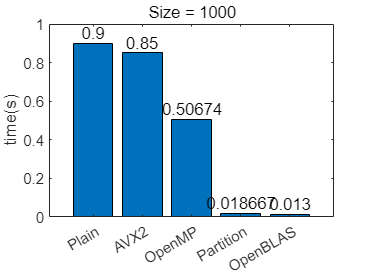

pc = [0.9 0.85 0.506742	0.018667 0.013];
x = ["Plain","AVX2","OpenMP","Partition","OpenBLAS"];
b = bar(x,pc);
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
ylim([0 1]),ylabel("time(s)")
title("Size = 1000")

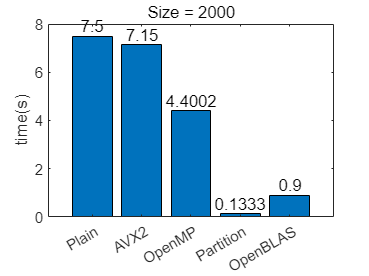

pc = [7.5 7.15 4.400234	0.133303 0.9];
x = ["Plain","AVX2","OpenMP","Partition","OpenBLAS"];
b = bar(x,pc);
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
ylim([0 8]),ylabel("time(s)")
title("Size = 2000")

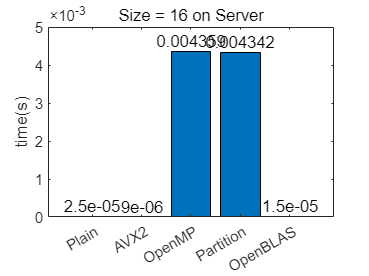

ser = [0.000025	0.000009 0.004359 0.004342 0.000015];
x = ["Plain","AVX2","OpenMP","Partition","OpenBLAS"];
b = bar(x,ser);
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
ylim([0 5e-3]),ylabel("time(s)")
title("Size = 16 on Server")

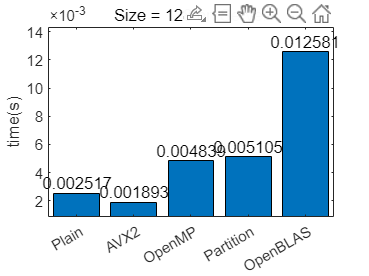

ser = [0.002517	0.001893 0.004839 0.005105 0.012581];
x = ["Plain","AVX2","OpenMP","Partition","OpenBLAS"];
b = bar(x,ser);
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
ylim([0 1.5e-2]),ylabel("time(s)")
title("Size = 128 on Server")

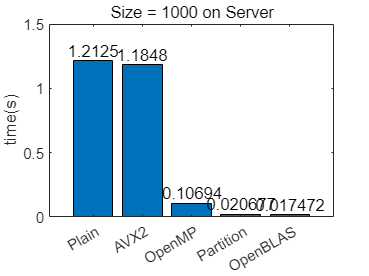

ser = [1.212488	1.184751 0.106935 0.020677 0.017472];
x = ["Plain","AVX2","OpenMP","Partition","OpenBLAS"];
b = bar(x,ser);
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
ylim([0 1.5]),ylabel("time(s)")
title("Size = 1000 on Server")

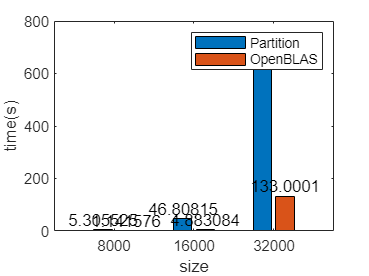

ser = [5.305525	1.141576; 46.808146 4.883084;658.688425 133.000096];
x = ["8000" "16000" "32000"];
b = bar(x,ser);
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(b(2).YData);
text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xlabel("size"),ylabel("time(s)")
legend(["Partition","OpenBLAS"])